## IV Praktikum 2022

### Vorbereitungsteil:

#### Aufgabe 1


$$|E| = \frac{1}{\sqrt2} 1V,
 $$
 
$$R_1=R_2=R=50 \Omega$$


#### 1. Bestimmen Sie Pmax. 

 
$$P_{max} = \frac{U_{eff}^2}{4R}$$
    


$$U_{eff}^2 = \left( \frac{|E|} {\sqrt{2}} \right)^2$$
 
$$\Rightarrow U_{eff}^2 = \left( \frac{1V}{\sqrt{4}} \right)^2 \Rightarrow  $$
   
$$U_{eff}^2 = \frac{1V^2}{4}
$$


$P_{max} = \frac{\frac{1V^2}{4}}{4R} = \frac{1V^2}{16R} = \frac 1 {800}  \frac {V^2} \Omega
$ $=1,25
$mW  

syms U_eff R E
P_max = U_eff^2/(4*R)

$$P\_max = \frac{{U_{\mathrm{eff}}}^{2}}{4\,R}$$

P_max = double(subs(P_max,[U_eff,R],[1/2,50]))*1000  %W --> mW

P_max = 1.2500

#### 2. Bestimmen Sie S21(jω).


$$S_{21} = k \frac {U_2} E = 2 \sqrt \frac{R_1} {R_2} \frac {U_2} {U_1} \frac{U_1} {E}$$
  
$$\Rightarrow$$
 
$$S_{21} = 2 \frac {U_2} E$$



$$U_2 = I * R_2 \\
I = \frac E {R_{ges}}$$
  
$$\Rightarrow$$
 
$$U_2 = \frac E {R_{ges}} R_2 \rightarrow  S_{21} = 2 \frac {R_2} {R_{ges}}$$



$$R_{ges} =  R + C||R \\
C||R = \frac1 {j \omega C+\frac 1 R}$$
        
$$\Rightarrow
$$
     
$$R_{ges} = R + \frac 1 {j \omega C + \frac 1 R}$$
  


$$S_{21} = 2 \frac R {R+ \frac R {j \omega C R + 1}} = \frac 2 {1+ \frac 1  {j \omega CR+1}} =  \frac 2 {\frac {j \omega CR + 1} {j \omega CR + 1}+ \frac 1  {j \omega CR+1}} =  \frac 2 {\frac {j \omega CR + 2} {j \omega CR + 1}} =2  \frac  {j \omega CR + 1} {j \omega CR + 2} = \frac  {2 \omega CR - 2j } { \omega CR -2j}$$


syms R omega C
R_ges = R + 1/(1i*omega*C+1/R);
S_21 = 2*R/R_ges

$$S\_21 = \frac{2\,R}{R+\frac{1}{\frac{1}{R}+C\,\omega \,\mathrm{i}}}$$

simplify(S_21,"Steps",640)

$$ans = 2-\frac{2}{2+C\,R\,\omega \,\mathrm{i}}$$

#### 3. Bestimmen Sie |S21(jω)|² und AdB(ω).

simplify(abs(S_21)^2,"Steps",3)

$$ans = \frac{4\,{\left|C\,R\,\omega -\mathrm{i}\right|}^{2}}{{\left|C\,R\,\omega -2\,\mathrm{i}\right|}^{2}}$$

S21_abs_quad = (4*C^2*R^2*omega^2)/(C^2*R^2*omega^2 + 4) + 4/(C^2*R^2*omega^2 + 4)

$$S21\_abs\_quad = \frac{4}{C^{2}\,R^{2}\,\omega^{2}+4}+\frac{4\,C^{2}\,R^{2}\,\omega^{2}}{C^{2}\,R^{2}\,\omega^{2}+4}$$

simpS21_abs_quad = simplify(S21_abs_quad,"Steps",10)

$$simpS21\_abs\_quad = 4-\frac{12}{C^{2}\,R^{2}\,\omega^{2}+4}$$

A_db = -10*log10(1/simpS21_abs_quad)

$$A\_db = -\frac{10\,\log\left(-\frac{1}{\frac{12}{C^{2}\,R^{2}\,\omega^{2}+4}-4}\right)}{\log\left(10\right)}$$

simA_db = simplify(A_db,"Steps",10)

$$simA\_db = -\frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}+4}{4\,C^{2}\,R^{2}\,\omega^{2}+4}\right)}{\log\left(10\right)}$$

#### 4. Zeichnen Sie AdB(ω) qualitativ. 

syms A_dB(omega)
A_dB = symfun(simA_db,[C,R,omega])

$$A\_dB(C, R, omega) = -\frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}+4}{4\,C^{2}\,R^{2}\,\omega^{2}+4}\right)}{\log\left(10\right)}$$

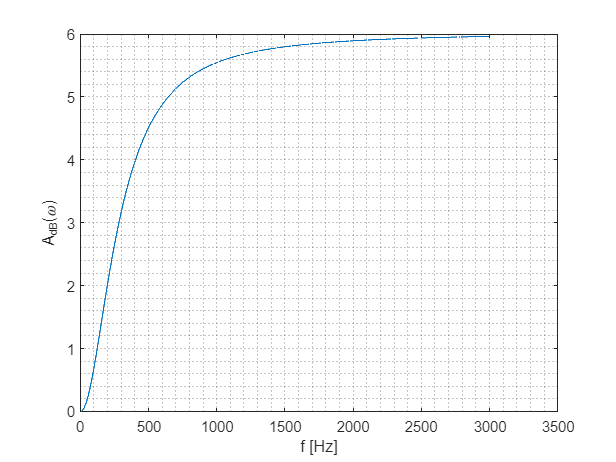

plot((A_dB(0.1,50,0:1/1000:3)))%Welche Werte für C?
xlabel ("f [Hz]")
ylabel("A_{dB}(\omega)")
grid("minor")

#### 5. Handelt es sich um ein Hochpass- oder ein Tiefpassfilter? Begründen Sie Ihre Antwort.

Anhand des Plot ist die Dämpfung für hohe Freq. groß und für kleine Freq. klein. Das Verhalten spiegelt einen Tiefpass wieder